# **Task 4**

# **Joint trajectory**

p1= (1, 0, 1) to p2=(√2/2, √2/2, 1.2)

"Controller command interpretation frequency –f = 100 Hz"

"Maximum linearvelocity –1 m/s"

"Maximum linearacceleration –10m/s^2"

type = LIN (trapezoidal)

clear 
p1 = [1 0 1];
p2 = [0.7071 0.7071 1.2];
%Assume final Time 
tf = 10;
% Number of points
N = 200;
% Divide our time from initial to fianl by number of points 
t = linspace(0,tf,N);
% Get the waypoints across the straight line
x = ((p2(1)-p1(1))/tf).*t + p1(1);
y = ((p2(2)-p1(2))/tf).*t + p1(2);
z = ((p2(3)-p1(3))/tf).*t + p1(3);

% Get the velocities for p1 & p2 
vx = ((p2(1)-p1(1))/tf);
vy = ((p2(2)-p1(2))/tf);
vz = ((p2(3)-p1(3))/tf);

velocity = [vx vy vz]

velocity =    -0.0293    0.0707    0.0200


J_config = zeros(3,100);
Joint_vel = zeros(3,100);
for joint_point = 1:N
    p_vec = [x(joint_point) y(joint_point) z(joint_point)];
    J_config(:,joint_point) = IK_ROBOT_POINTS(p_vec);
    if joint_point == 1 || joint_point == N
        Joint_vel(:,joint_point) = 0;
    else %Use Inverse Kinematics to convert task space trajectory into joint space vector.
        J =  calculate_jac(J_config(:,joint_point));
        %inv(J)*vel
        Joint_vel(:,joint_point) = J\velocity';
    end
end

q_position = zeros(3,25);
q_velocity = zeros(3,25);
q_acceleration = zeros(3,25);
Q_pos = [];
Q_vel = [];
Q_acc = [];
for num_of_points = 1:N-1
    t0 = t(num_of_points);
    tf = t(num_of_points+1);
    A = [1 t0 t0^2 t0^3;
         0 1 2*t0 3*t0^2;
         1 tf tf^2 tf^3;
         0 1 2*tf 3*tf^2;]; 
     %looping across every joint & point to find the b coffiecent 
     for joint_point = 1:3
         b = [J_config(joint_point,num_of_points) Joint_vel(joint_point,num_of_points) J_config(joint_point,num_of_points+1) Joint_vel(joint_point,num_of_points+1)]';
         %  inv(A) * b
         x =A\b;
         ti = linspace(t0,tf,25);%assign the results to the coeffs
         q_position(joint_point,:) = x(1)+x(2).*ti + x(3).*ti.^2 + x(4).* ti.^3;
         q_velocity(joint_point,:) = x(2) + 2*x(3).*ti + 3*x(4).* ti.^2;
         q_acceleration(joint_point,:) = 2*x(3)+ x(4)*6.*ti;
     end
     Q_pos = [Q_pos q_position];
     Q_vel = [Q_vel q_velocity];
     Q_acc = [Q_acc q_acceleration];
end
time = linspace(0,tf,4975);

# Plotting of the joint positions, velocities, acceleration

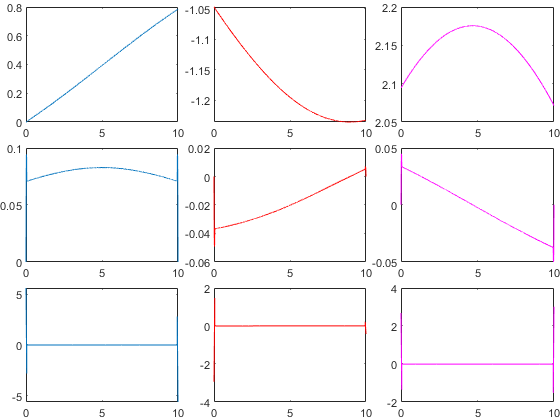

plt_3 = tiledlayout(3,3); % Requires R2019b or later
nexttile
plot(time,Q_pos(1,:),'DisplayName','q1_pos')
nexttile
plot(time,Q_pos(2,:),'r','DisplayName','q2_pos')
nexttile
plot(time,Q_pos(3,:),'m','DisplayName','q3_pos')
nexttile
plot(time,Q_vel(1,:),'DisplayName','q1_vel')
nexttile
plot(time,Q_vel(2,:),'r','DisplayName','q2_vel')
nexttile
plot(time,Q_vel(3,:),'m','DisplayName','q3_vel')
nexttile
plot(time,Q_acc(1,:),'DisplayName','q1_acc')
nexttile
plot(time,Q_acc(2,:),'r','DisplayName','q2_acc')
nexttile
plot(time,Q_acc(3,:),'m','DisplayName','q3_acc')
plt_3.Padding = 'none';
plt_3.TileSpacing = 'none'; 